clear all; clf;

% Parametry programu 
T = 1;              % okres [s]
N = 1000;           % liczba probek
dt = T/N; f0 = 1/T; % podstawa czasu [s], czest [Hz]
t = 0:dt:(N-1)*dt;  % wektor czasu
A = 1;  NF=60;      % amplituda i liczba wspolczynnikow sz F
f=0:f0:(NF-1)*f0;

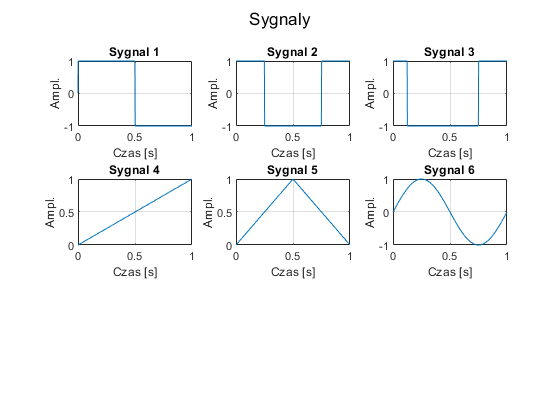

% Generacja sygnalow
x= [0 A*ones(1, N/2-1) 0 -A*ones(1, N/2-1)];
x(2, :)=[A*ones(1,N/4) 0 -A*ones(1,N/2-1) 0 A*ones(1,N/4-1)];
x(3, :)=[A*ones(1,N/8) 0 -A*ones(1,5*N/8-1) 0 A*ones(1,2*N/8-1)];
x(4, :)=A/T*t;
x(5, :)=[2*A/T*t(1:N/2+1) 2*A/T*t(N/2:-1:2)];
x(6, :)=sin(2*pi*t/T);

figure("Name", "Sygnaly");
sgtitle("Sygnaly")
for i=1:size(x, 1)
    subplot(size(x, 1)/2, floor(size(x, 1)/2), i);
    plot(t, x(i,:)); title(['Sygnal ' num2str(i)]); grid; xlabel('Czas [s]'); ylabel('Ampl.');
end
hold on;

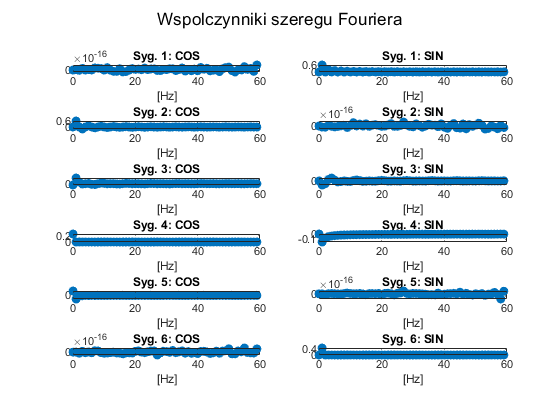

% Wyznaczaenie wspolczynnikow rozwiniecia sygnalu w szereg Fouriera
figure("Name", "Wspolczynniki szeregu Fouriera");
sgtitle("Wspolczynniki szeregu Fouriera");
a = zeros(size(x, 1), NF); b=a; c0 = zeros(1, size(x, 1));
for i=1:size(x, 1)
    % c0(i) = sum(x(i, :))/N; %skladowa stala, wartosc srednia NIE TRZEBA
    % A(1) to skladowa sta,a trzeba ja przeskalowac
    for k=0:NF-1
        ck=cos(2*pi*k*f0*t); sk=sin(2*pi*k*f0*t); %cosinus oraz sinuns o nr k
        a(i, k+1)=sum(x(i,:).*ck)/N;
        b(i, k+1)=sum(x(i,:).*sk)/N;
    end
    a(i, 1) = a(i, 1)/2;
    subplot(size(x, 1), 2, 2*i-1); stem(f,a(i,:),'filled'); xlabel('[Hz]'); title(['Syg. ' num2str(i) ': COS']);
    subplot(size(x, 1), 2, 2*i); stem(f,b(i,:),'filled'); xlabel('[Hz]'); title(['Syg. ' num2str(i) ': SIN']);
end

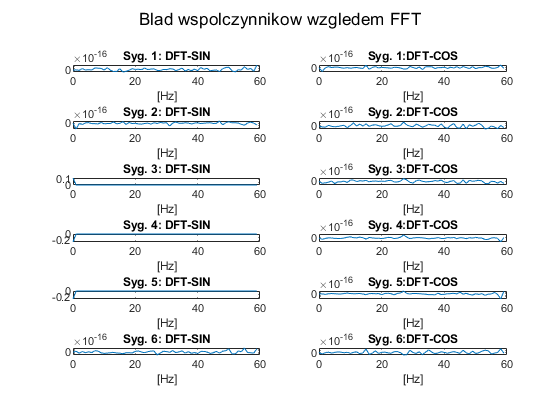

% Porownanie z FFT
figure("Name", "Blad wspolczynnikow wzgledem FFT")
sgtitle("Blad wspolczynnikow wzgledem FFT")
for i=1:size(x,1)
    X = fft(x(i,:), N)/N;
    X = conj(X);
    subplot(size(x, 1), 2, 2*i-1); plot(f, a(i,:) - real(X(1:NF) )); xlabel('[Hz]'); title(['Syg. ' num2str(i) ': DFT-SIN']);
    subplot(size(x, 1), 2, 2*i); plot(f, b(i,:) - imag( X(1:NF) )); xlabel('[Hz]'); title(['Syg. ' num2str(i) ':DFT-COS']);
end

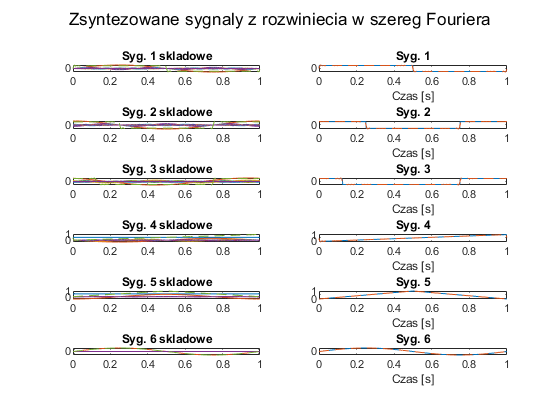

% Synteza sygnalow z wspolczynnikow
figure("Name", "Zsyntezowane sygnaly z rozwiniecia w szereg")
sgtitle("Zsyntezowane sygnaly z rozwiniecia w szereg Fouriera")
for i=1:size(x, 1)
    y=zeros(size(t)); y_temp=y;
    for k=0:NF-1
        y_temp = 2*a(i, k+1)*cos(2*pi*k*f0*t) + 2*b(i, k+1)*sin(2*pi*k*f0*t);
        y = y + y_temp;
        subplot(size(x, 1), 2, 2*i-1); plot(t ,y_temp); hold on;
    end
    subplot(size(x, 1), 2, 2*i-1); plot(t ,y, '--'); title(['Syg. ' num2str(i) ' skladowe']);
    subplot(size(x, 1), 2, 2*i); plot(t, x(i, :), t, y, '--'); xlabel('Czas [s]'); title(['Syg. ' num2str(i)]);
end